# Applied Digitalisation 2: Data Analysis - Assignment

## Assignment

The retention time of waste particles moving from Input to Output 1 should be calculated. The retention time should help to align the same waste bagde input to the same waste badge output. The waste particles had RFID tags attached to them in order to detect them in the input and output. 

## Data filtration

tagreadshw2.Timestamp = datetime(tagreadshw2.Timestamp, 'InputFormat','uuuu-MM-dd HH:mm:ss,SSS');

desired_tag = '4D554C';

condition = strncmpi(string(tagreadshw2.EPC), desired_tag, 6);

filtered_table = tagreadshw2(condition, :);

### Explanation

A condition was created that contains the EPC tag of MUL and filters through the table to eliminate all datapoint that are not part of MUL.

For this, the 'desired_tag' was created. This string contains the EPC start of MUL. Then the condition was defined. In the condition, all EPCs of the tagreads were compared to the 'desired_tag'. All datapoints that fulfill this condition were added to the table 'filtered_table'

### Challenges

It took a long time to read through all the documentation to find the functions that were useful.

### AI

AI was used to asked questions like 'How to filter a table'.

## Checking if tags are detected at both readers

To calculate the retention time, a value for both readers 1 and 2 are necessary. Therefore, the filtered_table was sorted again in order to check if there are EPCs that do not have a value for both readers.

% creating a tag and a condition for each reader.
desired_tag_rd_1 = 'Rd1';
desired_tag_rd_2 = 'Rd2';

condition_rd_1 = strncmpi(string(filtered_table.ReaderAntenna), desired_tag_rd_1, 3);
condition_rd_2 = strncmpi(string(filtered_table.ReaderAntenna), desired_tag_rd_2, 3);

% creating a list for each reader.
reader_1 = filtered_table(condition_rd_1, :);
reader_2 = filtered_table(condition_rd_2, :);


### Explanation

Ex_1 (old): To check if each particle passed both readers at least once, two lists were created. One list for each Reader (reader_1 and reader_2). To fill these lists, conditions were used again. This time, the condition looked at the ReaderAntenna column. Those lists were then compared to see which EPCs are on both lists. All the EPCs that were only available on one of those lists were sorted out.

Ex_2 (new): After further concideration some code got deleted as it was deemed unnecessary.  Now the table gets sorted according to matching EPCs later. Two tables got created (reader_1 and reader_2) with all the values of each reader. Each table contains all MUL EPCs with the respective reader values. 

### Challenges

It took me hours to think of a logic in order to check if all EPCs are at least once detected by each reader since no guidence in the assignment paper is provided. It also took me a long time to figure out how I filter the tables properly and how to further process the outputs that i generated. 

After stumbeling over the function 'innerjoin' that is used later in the code, the sorting and crosschecking the tables with the EPCs was deemed unnecessary. 

### AI 

AI was used to asked questions on how to check for common tags in tables and follow up questions. It was mainly used to think of a logic and which functions I can use. The code is mine.

## Calculating the retention time

The retention time is calculated by substracting the timestamp of reader 2 from the timestamp of reader 1. For each unique EPC, a median timestamp for reader 1 and 2 was calculated and those median timestamps were used to calculate the retention time.

% creating a new table with the median timestamps of all unique EPCs for
% each reader
median_rd_1 = groupsummary(reader_1, 'EPC', 'median', 'Timestamp');
median_rd_2 = groupsummary(reader_2, 'EPC', 'median', 'Timestamp');

joined_median_times = innerjoin(median_rd_1, median_rd_2, 'Keys', 'EPC');

joined_median_times.ret_time = joined_median_times.median_Timestamp_median_rd_2 - joined_median_times.median_Timestamp_median_rd_1;


### Explanation

Ex_1 (old): After reconsideration, the sorted_EPC table was not used for this step as the timestamps of each reader were needed separatly anyways.

Ex_2 (new): After stumbeling across the function 'innerjoin', unnecessary code got deleted. With the function 'groupsummary' all medians of the timestamps for each unique EPC gets calculated. The median_rd_1 and median_rd_2 tables contain now the medians and a 'counter' that gives information about how many EPCs were taken into account for the calculation of the median. The 'innerjoin' function combines both tables and the EPC is used as a key. The key defines that all values in one row with the same key should be combined. Therefore, only one table exist now and each row has one unique EPC that got detected in both readers. This is the case because all keys (EPCs) that cannot be found in both tables (median_rd_1 and median_rd_2) are deleted automatically by the function 'innerjoin'.

After the tables are joined together, the retention time was calculated with the formula:

ret_time =output time - input time

### Challenges

This part was less challenging but took a long time anyways. First, I thought that I was almost finished and I only had to calculate the retention time. However, with my initial code, I needed a way to join together two tables. This is were I stumbeld across the function 'innerjoin' which allowed me to revise my code and make it shorter and more compact.

### AI

AI was used to find functions that might be useful for me to use. This is were I found 'innerjoin'.

## Plotting the data

The results of the calculations above should be plotted in a box-whisker-Plot.

joined_median_times = 45×6 table
              EPC               GroupCount_median_rd_1    median_Timestamp_median_rd_1    GroupCount_median_rd_2    median_Timestamp_median_rd_2     ret_time 
    ________________________    ______________________    ____________________________    ______________________    ____________________________    __________

    4D554C2E56312E4C472E3031              18                  17-May-2022 13:44:23                  31                  17-May-2022 13:45:04        0.00047392
    4D554C2E56312E4C472E3032              20                  17-May-2022 14:04:26                  19                  17-May-2022 14:05:14        0.00055779
    4D554C2E56312E4C472E3033              14                  17-May-2022 13:20:40                  35                  17-May

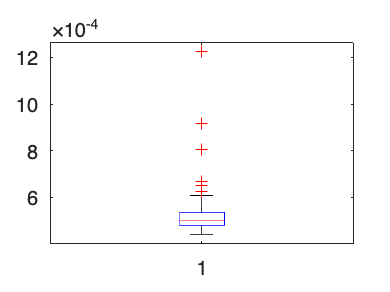

boxplot(datenum(joined_median_times.ret_time))

### Explanation

The boxplot function was used to plot the box-whisker-plot. The date data had to be converted to a different format again. For this, the function datenum was used.

### Challenges

No particular challenges were encountered at this step. Since we already plotted other graphs in class and in the other homework assignment, I figured there was a function for a box-whisker-plot as well. 

### AI

AI was used to find the functions boxplot and datenum.

## Conclusion

### AI

AI was used throughout this assignment. Mainly to find functions that might be usedful for my case. Howerver, all functions used in this code were revised and looked at in the documentation as well. 

### Challenges

#### In this Assignment

The biggest challenges were in the beginning. It was very difficult to figure out how to properly handle tables that are that big. It took me a long time to figure out the logic behind each step without guidence. It was also difficult to figure out what 'one step' in programming might be. I had no feeling for what was a proper next step. I spend around 8 hours on this assignment at home. However, along the way, I found more and more functions that were useful for my case which allowed me to shorten my code with each step I progressed. 

I do see how the explanations and the structure of this report might be a bit confusing but I did not want to get rid of the documented struggels of mine along the way as it is a learning PROCESS. It was also the first time I proberly wrote a report about a code. It is still difficult for me to find the correct words to descripe code.

#### General Feedback

This is meant to be a general Feedback for this course and is not necessarly part of this report. Feel free to ignore this part as I do see the assignment fulfilled. However, this can be a course, where both parties learn something. Everything written down is of course my own personal opinion.

This assignment was too difficult and the difficulty jump between lecture 1 and 2 is too big. Learning to program is about repetition and to get a feeling of how the language works. This course definatly did not grant us enough time to repeat the learnt progress often enough. I had to look up the same functions and logics several times which is very time consuming and frustrating in a big assignment like this. Digital sorting lab for example gave us a homework with ca 15 small exercises that had the same logic (e.g. creating your own function. The exercises were all about creating your own function). 

Learning a programming language is like learning a new language overall. You can not ask students to learn the basic vocabulary in the first class and then to read an entire book in the second class.

However, in the end I learnt a lot but it was also very frustrating. Without AI, I probably would not have managed to solve this issue. I would have appreciated more preparation in the coures before we got to this assignment though. 

Giving more guidence in the biginning to solve assignments like this might prevent frustrations and help having a better learning experience.